%======================================
%created by Brandon Nyugen
%revised by Yoichi Watanabe
%last revised on 2/10/2024 - the best version so far
%======================================

%set parameters
clearvars;
%measurement settings
format shortG
% magnet model: D32N52
% magnet parameters
%3/16
%1/8
diameter = 1/16*25.4; %mm
height = 1/32*25.4; %mm
%Br_max = 14800*0.1; %mT [specification]
Br_max =  14800*0.1;
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 4.5; %mm
num_sensors=16;

Specify the common part of the file name

file_prefix = 'C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\MLX02102024_D101N52_z12mm\sensor_';
%file_prefix = 'C:\Users\watan016\Dropbox\Research\Project_LGK\GK_Motion_tracking\Motion_data\16sensor_data_01312024\purepani magnetic-sensor-data main MLX01312024_gamma3\sensor_';
%file_prefix = 'C:\Users\watan016\Dropbox\Research\Project_LGK\GK_Motion_tracking\Motion_data\purepani magnetic-sensor-data main MLX02072024_D32N52_test4\sensor_';
file_suffix = '_averages.csv';

% read the magnetic field vector data measured by 16 sensors
% Loop to create variables sen1, sen2, ..., sen16
for sensor_num = 1:num_sensors
    % Construct the file name for the current sensor
    file_name = [file_prefix, num2str(sensor_num), file_suffix];
    
    try
        % Read the CSV file using readtable
        data_table = readtable(file_name, 'Delimiter', ',', 'VariableNamingRule', 'preserve');
        
        % Extract data matrix
        data_matrix = cell2mat(cellfun(@eval, data_table{:, :}, 'UniformOutput', false));
        
        % Create a variable name for the data
        variable_name = ['sen', num2str(sensor_num)];
        
        % Assign the data to a variable with a dynamically generated name
        eval([variable_name, ' = data_matrix;']);
    catch
        % Handle any errors (you can add specific error handling if needed)
        fprintf('Error reading data for sensor %d\n', sensor_num);
    end
end

sensor_actual = [
    0, 0, 0;
    -4.5, 0, 0;
    -9.0, 0, 0;
    -13.5, 0, 0;
    0, 4.5, 0;
    -4.5, 4.5, 0;
    -9.0, 4.5, 0;
    -13.5, 4.5, 0;
    0, 9.0, 0;
    -4.5, 9.0, 0;
    -9.0, 9.0, 0;
    -13.5, 9.0, 0;
    0, 13.5, 0;
    -4.5, 13.5, 0;
    -9.0, 13.5, 0;
    -13.5, 13.5, 0
    ];

sensor_actual = sensor_actual + [13.5/2 -13.5/2 0];

%the number of data points
num_data = length(sen1);
% Create a cell array to store all rows
all_sen = cell(num_data, num_sensors);

% Access each row of each matrix and store in the cell array
for row = 1:num_data
    for sensor = 1:num_sensors
        sens = eval(['sen', num2str(sensor)]);
        all_sen{row, sensor} = sens(row,:);
    end
end

multipreds = [];
multifvals = [];
for t = 1:num_data
    tt = [all_sen{t,:}];
    costfun = @(v)mmcost(v, B_t, sensor_actual, tt, 1, num_sensors);
    nonlcon = @con;
    
    x0 = [0, 0, 1, 5, 5, 55];
    %x0 = [0 0 5];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-1, -1, -1, -100, -100, 0];
    ub = [1, 1, 1, 100, 100, 100];
    %lb = [-100 -100 0];
    %ub = [100 100 0];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    multipreds = [multipreds; locs];
    multifvals = [multifvals; fval];
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

%

%calculate the distance between a point and the initital point
multiang = multipreds(:,1:3);
multiloc = multipreds(:,4:6);
%multiloc = multipreds(:,1:3);
new_multiloc = multiloc;
r0 = [multiloc(1,1) multiloc(1,2) multiloc(1,3)];
testx =sqrt(sum((new_multiloc-r0).^2, 2));

%calculate the expected displacement of measurement points r.t. the first pos.
%6x6 points
for i = 0:5
    for j= 0:5
        zi(6*i+j+1) = sqrt(i^2 + j^2);
    end
end

zi = zi';
fliers = find(testx > 10)


fliers =

  0×1 empty double column vector




zi(fliers) = [];
testx(fliers) = [];

SSR = sum((zi - testx).^2)

SSR =        88.196


SST = sum((zi - mean(testx)).^2)

SST =        105.53


R2 = 1 - SSR/SST

R2 =       0.16428


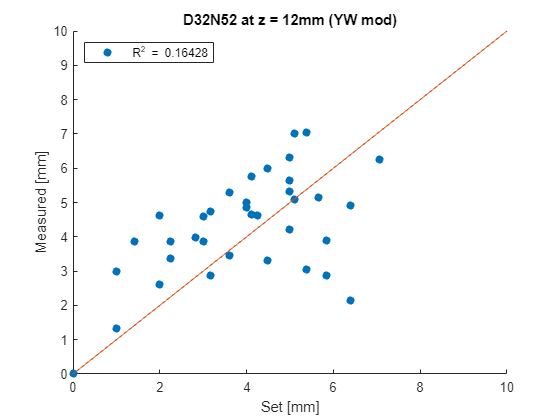


figure(1)
scatter(zi, testx, 'filled')
hold on;
plot(0:10,0:10)
xlabel("Set [mm]")
ylabel('Measured [mm]')
title('D32N52 at z = 12mm (YW mod)')
legend(['R^2 = ', num2str(R2)], Location = 'northwest')
hold off;

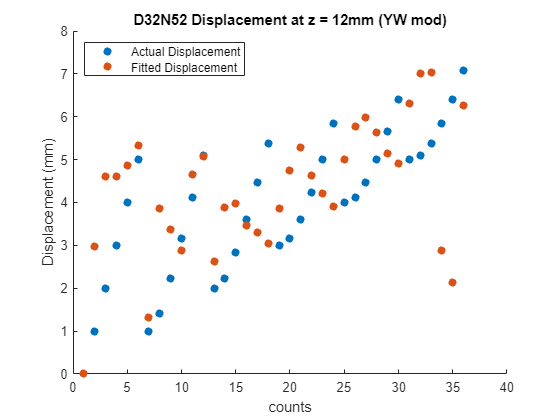

disp = zi;
multidisp = testx;
figure(2)
scatter(1:length(disp), disp, 'filled')
hold on;
scatter(1:length(multidisp), multidisp, 'filled')
title('D32N52 Displacement at z = 12mm (YW mod)')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function mm = mmcost(v, B_t, sensor_grid, sensor_data, s1, s2)
%modifed by Yoichi Watanabe, last updated on 2/10/2024
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
loc = [v(4) v(5) v(6)];
%x y z coordinate of the center of num_sensors arrays
%H_0 = repelem([0 0 1], 1, 1);
%loc = [v(1) v(2) v(3)];
s = sensor_data;
%--------rotate the array plane relative to the global coordinate
epsilon = 1e-12;
n1 = [1 0 0];
n2 = [0 1 0];
n3 = [0 0 1];
n_global = [n1; n2; n3];
h0_m = norm(H_0)+epsilon;
H_1 = H_0./h0_m;
rotmtx = rotation_mat(n3, H_1);
rotx = @(t) [1 0 0; 0 cos(t) -sin(t) ; 0 sin(t) cos(t)];
rot_angle=0; %changed from pi to 0 (2/10/2024)
X_t = rotx(rot_angle)*sensor_grid';
sensor_grid_t = (rotmtx * X_t)';
%------------------------------------
mm = 0;
for i = s1:s2
    X = sensor_grid_t(i, :) - loc;
    R = sqrt(sum(X.^2, 2));
    %changed H_0 to H_1 on 2/10/2024
    mm = mm + sum((s(3*i-2:3*i) - ...
        B_t * (3 * dot(H_1, X, 2).* X./ R.^5 - H_1./ R.^3)).^2);
end
end

function R = rotation_mat(a, b)
u = a'/norm(a');                      % a and b must be column vectors
v = b'/norm(b');                      % of equal length
N = length(u);
S = reflection( eye(N), v+u );      % S*u = -v, S*v = -u
R = reflection( S, v );             % v = R*u
end

function v = reflection( u, n )     % Reflection of u on hyperplane n.
%
% u can be a matrix. u and v must have the same number of rows.

v = u - 2 * n * (n'*u) / (n'*n);
end